**1.Power and Torque Requirements**

% GN = group number
gn = 3

gn = 3

%Power to be transmitted
pwr = mod(gn, 5)*5 + 20 %hp

pwr = 35

%Given Speed Input
speed_in = mod(gn, 6)*100 + 1750 %rev/min

speed_in = 2050

%Max speed
max_is = speed_in*1.2 %rev/min

max_is = 2460


min_rel = 0.995

min_rel = 0.9950

min_pwreff = 0.95

min_pwreff = 0.9500

min_ss_sr = 20

min_ss_sr = 20


ss_sr = min_ss_sr

ss_sr = 20

%Torque inputs and outputs
torque_in = pwr*5252/speed_in %ft-lb

torque_in = 89.6683

torque_out = torque_in*ss_sr

torque_out = 1.7934e+03

speed_out = speed_in/ss_sr

speed_out = 102.5000

**2.Gear Specifiction**

e = 1/ss_sr % steady state speed reduction

e = 0.0500


syms N2 N3 N4 N5 

pressure_angle = 20 %deg

pressure_angle = 20

k = 1

k = 1

m = 1/sqrt(e)

m = 4.4721

min_N = ceil(2*k*(m+sqrt(m^2+(1+2*m)*sind(pressure_angle)^2))/((1+2*m)*sind(pressure_angle)^2))

min_N = 16


N2 = min_N

N2 = 16

N4 = min_N

N4 = 16

N3 = floor(m*N2)

N3 = 71

N5 = N3

N5 = 71



speed_out_check = (N2/N3)*(N4/N5)*speed_in

speed_out_check = 104.1063

ss_sr_check = speed_in/speed_out_check

ss_sr_check = 19.6914

Gear ratio is slightly less than required gear ratio - have to round N3 and N5 up.

N3 = ceil(m*N2)

N3 = 72

N5 = N3

N5 = 72

%These tooth sizes dont seem to have a gear capable of supporting the load,
%doubling up the teeth may work
N2 = 2*N2

N2 = 32

N4 = N2

N4 = 32

N3 = 2*N3

N3 = 144

N5 = N3

N5 = 144

disp(N2/N3)

    0.2222



speed_out_check = (N2/N3)*(N4/N5)*speed_in

speed_out_check = 101.2346

ss_sr_check = speed_in/speed_out_check

ss_sr_check = 20.2500

Minimum speed reduction met.

ss_sr = ss_sr_check

ss_sr = 20.2500

torque_out = torque_in*ss_sr

torque_out = 1.8158e+03


e = 1/ss_sr

e = 0.0494

speed_out = speed_out_check

speed_out = 101.2346

shaft_speed = (N2/N3)*speed_in

shaft_speed = 455.5556


shaft_torque = torque_in*(speed_in/shaft_speed)

shaft_torque = 403.5073

Gear Dimension Spec

%pn is diametral pitch, must match
%dn is pitch diameter, calculated
p2 = 8

p2 = 8

p4 = p2

p4 = 8

p3 = p2

p3 = 8

p5 = p2

p5 = 8

d2 = N4/p2 %in

d2 = 4

d4 = d2

d4 = 4

d3 = N5/p2

d3 = 18

d5 = d3

d5 = 18

%Pitch line velocities and transmitted loads
syms V23 V45 W23t W45t
V23 = pi*d2*speed_in/12

V23 = 2.1468e+03

V45 = pi*d5*speed_out/12 

V45 = 477.0567

W23t =33000*(pwr)/V23

W23t = 538.0213

W45t =33000*(pwr)/V45 

W45t = 2.4211e+03

Gear 4 Wear Analysis

%Get geometry factor
mn = 1 %for spur gears

mn = 1

mg = d5/d4

mg = 4.5000

I = cos(pressure_angle)*sin(pressure_angle)/(2*mn)*(mg/(mg+1))

I = 0.1524


%Assume quality factor
Qv = 7

Qv = 7


%Kv Dynamic Factor
B = 0.25*(12-Qv)^(2/3)

B = 0.7310

A = 50 + 56*(1-B)

A = 65.0638

Vtmax = (A + (Qv-3))^2

Vtmax = 4.7698e+03

Kv = ((A+sqrt(Vtmax))/A)^B

Kv = 1.6969


%Face Width
F = 2.5 %in

F = 2.5000


%Km Load Distribution Factor
syms Cmf Cmc Cpf Cpm Cma Ce
Cpf = F/(10*d2) - 0.0375 + 0.0125*F

Cpf = 0.0563

%Assume Cpm 1
Cpm = 1

Cpm = 1

% Constants for Cma 
A = 0.127

A = 0.1270

B = 0.0158

B = 0.0158

C = -0.93E-4

C = -9.3000e-05

Cma = A + B*F + C*(F^2)

Cma = 0.1659

Ce = 1 

Ce = 1

Cmc = 1 

Cmc = 1

Km = 1 + Cmc*(Cpf*Cpm + Cma*Ce)

Km = 1.2222


%Elastic Coefficient
Cp = 2300

Cp = 2300


%Assume overload, surface finish, size factors = 1
Ko = 1

Ko = 1

Cf = 1

Cf = 1

Ks = 1

Ks = 1


%Pitting Resistance/Contact Stress 
Sc45 = Cp*sqrt(W45t*Ko*Kv*Ks*Km*Cf/(p4*F*I)) %psi

Sc45 = 9.3349e+04

% sigmaC is Sc45.
sigmaC = Sc45;

%Life factor of the gear
T = 12000 %Hours 

T = 12000

L4 = T*(60)*(shaft_speed) %hours *60(min/hr) * rpm = cycles or revolutions

L4 = 328000000

%Stress cycle factor
Zn = 0.85 %Figure 14-15

Zn = 0.8500

%Reliability Factor
R = 0.995

R = 0.9950

Kr = 0.5 - 0.109*log(1-R)

Kr = 1.0775

%Temperature Factor, Temp from -25 to 50 C
Kt = 1

Kt = 1

%Hardness Ratio Factor, used only for the gear
CH = 1

CH = 1

% Sc,allowable is the samw as sigmaC (mentioned above around line 105)
%let factor of safety = 1.2
Gear_FOS = 1.2

Gear_FOS = 1.2000

Sc = Gear_FOS*sigmaC/Zn

Sc = 1.3179e+05

%Sc was 2.4767e+05 table 14-6 provides grade 3 material at 275 000
Sc = 275000

Sc = 275000

nc = Sc*Zn/sigmaC % factor of safety for wear

nc = 2.5040

% n - 2.264, acceptable

Gear 4 Bending

%Geometry factors
J = 0.27    % from Figure 14-6

J = 0.2700

Kb = 1

Kb = 1


sigmaBend4 = W45t*Kv*(Km/J)*(p4/F)

sigmaBend4 = 5.9511e+04

Yn =   0.9        %Figure 14-14, using L4 (approx. 10^8)

Yn = 0.9000

% We made use of grade 3 steel not grade 2
% st is the the tensile stress from table 14-3
St = 75000

St = 75000

sigmaAllowed  = St * Yn

sigmaAllowed = 67500


n = sigmaAllowed/sigmaBend4

n = 1.1342

%with gear diameters that dont work in the doc get n = 0.89, have to redo
%with different gears. Look at Azhars note in the doc

Gear 3 Wear Analysis

%Get geometry factor
mn = 1 %for spur gears

mn = 1

mg = d5/d4

mg = 4.5000

I = cos(pressure_angle)*sin(pressure_angle)/(2*mn)*(mg/(mg+1))

I = 0.1524


%Assume quality factor
Qv = 7

Qv = 7


%Kv Dynamic Factor
B = 0.25*(12-Qv)^(2/3)

B = 0.7310

A = 50 + 56*(1-B)

A = 65.0638

Vtmax = (A + (Qv-3))^2

Vtmax = 4.7698e+03

Kv = ((A+sqrt(Vtmax))/A)^B

Kv = 1.6969


%Face Width
F = 2 %in

F = 2


%Km Load Distribution Factor
syms Cmf Cmc Cpf Cpm Cma Ce
Cpf = F/(10*d2) - 0.0375 + 0.0125*F

Cpf = 0.0375

%Assume Cpm 1
Cpm = 1

Cpm = 1

% Constants for Cma 
A = 0.127

A = 0.1270

B = 0.0158

B = 0.0158

C = -0.93E-4

C = -9.3000e-05

Cma = A + B*F + C*(F^2)

Cma = 0.1582

Ce = 1 

Ce = 1

Cmc = 1 

Cmc = 1

Km = 1 + Cmc*(Cpf*Cpm + Cma*Ce)

Km = 1.1957


%Elastic Coefficient
Cp = 2300

Cp = 2300


%Assume overload, surface finish, size factors = 1
Ko = 1

Ko = 1

Cf = 1

Cf = 1

Ks = 1

Ks = 1


%Pitting Resistance/Contact Stress 
Sc45 = Cp*sqrt(W45t*Ko*Kv*Ks*Km*Cf/(p3*F*I)) %psi

Sc45 = 1.0323e+05

% sigmaC is Sc45.
sigmaC = Sc45;

%Life factor of the gear
T = 12000 %Hours 

T = 12000

L3 = T*(60)*(shaft_speed) %hours *60(min/hr) * rpm = cycles or revolutions

L3 = 328000000

%Stress cycle factor
Zn = 0.85 %Figure 14-15

Zn = 0.8500

%Reliability Factor
R = 0.995

R = 0.9950

Kr = 0.5 - 0.109*log(1-R)

Kr = 1.0775

%Temperature Factor, Temp from -25 to 50 C
Kt = 1

Kt = 1

%Hardness Ratio Factor, used only for the gear
CH = 1

CH = 1

% Sc,allowable is the same as sigmaC (mentioned above around line 105)
%let factor of safety = 1.2
Gear_FOS = 1.2

Gear_FOS = 1.2000

Sc = Gear_FOS*sigmaC/Zn

Sc = 1.4574e+05

%Sc was 2.4767e+05 table 14-6 provides grade 3 material at 275 000, grade 1 (Sc = 180000)
Sc = 180000

Sc = 180000

nc = Sc*Zn/sigmaC % factor of safety for wear

nc = 1.4821

Gear 3 Bending

%Geometry factors
J = 0.27    % from Figure 14-6

J = 0.2700

Kb = 1

Kb = 1


sigmaBend3 = W23t*Kv*(Km/J)*(p3/F)

sigmaBend3 = 1.6173e+04

Yn =   0.9        %Figure 14-14, using L4 (approx. 10^8)

Yn = 0.9000

% Grade 3 gives FOS of 5, can lower cost by choosing grade 1 (st = 55000)
St = 55000

St = 55000

sigmaAllowed  = St * Yn

sigmaAllowed = 49500


n = sigmaAllowed/sigmaBend3

n = 3.0606

%n == 1.134, acceptable

**3. Shaft Layout/Force Analysis**

Assume bore size of 1 in to start

Both gears will be keyed to support torque transmission 

%Length Calculation (in)
%Bearing Width
fwb = 0.75

fwb = 0.7500

%Gap between bearings and gears
dbg = 0.5

dbg = 0.5000

%distance between centers of gears 3 and 4
dspace = 3

dspace = 3

%Gear Face Widths
fw3 = 2 %in

fw3 = 2

fw4 = 2.5 %in

fw4 = 2.5000

fw5 = fw3

fw5 = 2

fw2 = fw4

fw2 = 2.5000

Lint = fwb*2 + 2*dbg + dspace + fw3+ fw4

Lint = 10


T5 = -torque_out

T5 = -1.8158e+03

T4 = shaft_torque

T4 = 403.5073

T3 = -T4

T3 = -403.5073

T2 = torque_in

T2 = 89.6683


shaft_radius = 0.75 %inches

shaft_radius = 0.7500


shear5 = (2/pi)*(T5/(shaft_radius/12)^3)*0.00694 %psi

shear5 = -3.2860e+04

shear4 = (2/pi)*(T4/(shaft_radius/12)^3)*0.00694 %psi

shear4 = 7.3022e+03

shear3 = (2/pi)*(T3/(shaft_radius/12)^3)*0.00694 %psi

shear3 = -7.3022e+03

shear2 = (2/pi)*(T2/(shaft_radius/12)^3)*0.00694 %psi

shear2 = 1.6227e+03

shear_max = shear5

shear_max = -3.2860e+04


%output shaft material: 1030 HR steel
%shaft 3_4 (middle shaft): 1006 HR steel
%input shaft: 1006 HR steel

%Gear Forces
F3t = torque_in/(d2/24) %zforce

F3t = 538.0098

F3n = F3t*tand(20) %yforce

F3n = 195.8195


F4t = -T4/(d4/24) %lbf, tangential

F4t = -2.4210e+03

F4n = F4t*tand(20) %normal

F4n = -881.1879


%Bearing Forces
syms B1z B2z B1y B2y
dg3 = fwb+ dbg + fw3/2 %distance of gear 3

dg3 = 2.2500

dg4 = dg3+fw3/2+ dspace + fw4/2

dg4 = 7.5000

db2 = dg4+ fw4/2 + dbg + fwb/2 %distance of bearing 2

db2 = 9.6250


%Solving for B2z
B2z = double(solve(0 == F3t*dg3/12 + F4t*dg4/12 + B2z*db2/12)) %z force of bearing 2

B2z = 1.7608e+03

%Solving for B1z
B1z = double(solve(0 == F3t + F4t + B2z + B1z))

B1z = 122.2749


%Solving for B2y
B2y = double(solve(0 == F3n*dg3/12 + F4n*dg4/12 + B2y*db2/12)) %y force of bearing 2

B2y = 640.8639

%Solving for B1z
B1y = double(solve(0 == F3n + F4n + B2y + B1y))

B1y = 44.5044

Shear and Bending Moment Diagrams

XZ Plane

syms x 
%XZ Plane
%Shear Force
Vxz = piecewise(0<x<dg3,B1z,dg3<x<dg4,B1z+F3t,dg4<x<db2,B1z+F3t+F4t,db2<x<Lint, F3t + F4t + B2z + B1z)

$$Vxz = \left\{ \begin{array}{cl} \frac{55146}{451} & \text{ if }x\in \left(0,\frac{9}{4}\right)\\ \frac{5807925648191763}{8796093022208} & \text{ if }x\in \left(\frac{9}{4},\frac{15}{2}\right)\\ -\frac{3871950432127841}{2199023255552} & \text{ if }x\in \left(\frac{15}{2},\frac{77}{8}\right)\\ \frac{1}{35184372088832} & \text{ if }x\in \left(\frac{77}{8},10\right) \end{array}\right.$$

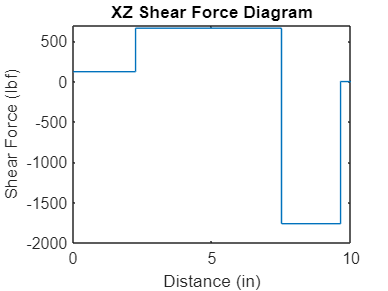

figure()
fplot(Vxz,[0 Lint])
ylim([-2000 700])
title('XZ Shear Force Diagram')
xlabel('Distance (in)')
ylabel('Shear Force (lbf)')


%Bending Moment
Mxz = piecewise(0<x<dg3,B1z*x,dg3<x<dg4,x*B1z+(x-dg3)*F3t,dg4<=x<db2,x*B1z+(x-dg3)*F3t+(x-dg4)*F4t)

$$Mxz = \left\{ \begin{array}{cl} \frac{55146\,x}{451} & \text{ if }x\in \left(0,\frac{9}{4}\right)\\ \frac{2619374467334485203\,x}{3967037953015808}-\frac{42591454753406265}{35184372088832} & \text{ if }x\in \left(\frac{9}{4},\frac{15}{2}\right)\\ \frac{596280366547687575}{35184372088832}-\frac{6984998579558625525\,x}{3967037953015808} & \text{ if }x\in \left[\frac{15}{2},\frac{77}{8}\right) \end{array}\right.$$

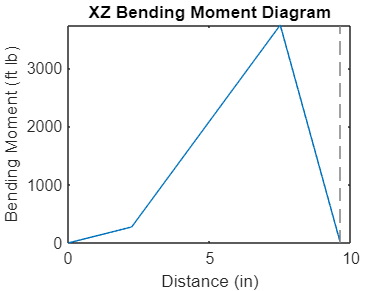

figure()
fplot(Mxz,[0 Lint])
title('XZ Bending Moment Diagram')
xlabel('Distance (in)')
ylabel('Bending Moment (ft lb)')

XY Plane

Vxy = piecewise(0<x<dg3,B1y,dg3<x<dg4,B1y+F3n,dg4<x<db2,B1y+F3n+F4n,db2<x<Lint, F3n + F4n + B2y + B1y)

$$Vxy = \left\{ \begin{array}{cl} \frac{48933149508635}{1099511627776} & \text{ if }x\in \left(0,\frac{9}{4}\right)\\ \frac{4227824117546079}{17592186044416} & \text{ if }x\in \left(\frac{9}{4},\frac{15}{2}\right)\\ -\frac{704637352924347}{1099511627776} & \text{ if }x\in \left(\frac{15}{2},\frac{77}{8}\right)\\ 0 & \text{ if }x\in \left(\frac{77}{8},10\right) \end{array}\right.$$

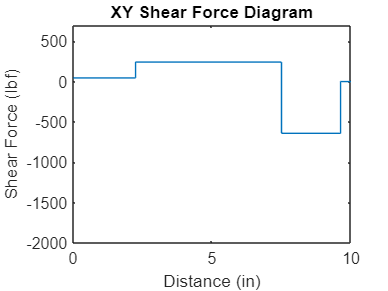

figure()
fplot(Vxy,[0 Lint])
ylim([-2000 700])
title('XY Shear Force Diagram')
xlabel('Distance (in)')
ylabel('Shear Force (lbf)')


Mxy = piecewise(0<x<dg3,B1y*x,dg3<x<dg4,x*B1y+(x-dg3)*F3n,dg4<=x<db2,x*B1y+(x-dg3)*F3n+(x-dg4)*F4n)

$$Mxy = \left\{ \begin{array}{cl} \frac{48933149508635\,x}{1099511627776} & \text{ if }x\in \left(0,\frac{9}{4}\right)\\ \frac{4227824117546079\,x}{17592186044416}-\frac{31004043528671271}{70368744177664} & \text{ if }x\in \left(\frac{9}{4},\frac{15}{2}\right)\\ \frac{434056609401397689}{70368744177664}-\frac{11274197646789553\,x}{17592186044416} & \text{ if }x\in \left[\frac{15}{2},\frac{77}{8}\right) \end{array}\right.$$

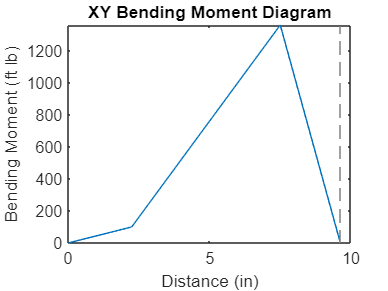

figure()
fplot(Mxy,[0 Lint])
title('XY Bending Moment Diagram')
xlabel('Distance (in)')
ylabel('Bending Moment (ft lb)')

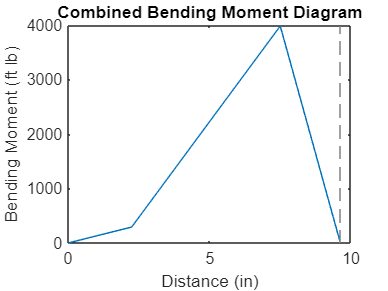


Mavg(x) = (Mxz.^2+Mxy.^2).^.5;
figure()
fplot(Mavg,[0 Lint])
title('Combined Bending Moment Diagram')
xlabel('Distance (in)')
ylabel('Bending Moment (ft lb)')

Mavgval = Mavg([0:0.01:13]);
Mpeak = double(max(Mavgval))

Mpeak = 3.9817e+03


%Torque along x
Tyz = piecewise(x<dg3,0,dg3<x<dg4,T3, dg4<x<Lint, T3+T4)

$$Tyz = \left\{ \begin{array}{cl} 0 & \text{ if }x<\frac{9}{4}\\ -\frac{82719}{205} & \text{ if }x\in \left(\frac{9}{4},\frac{15}{2}\right)\\ 0 & \text{ if }x\in \left(\frac{15}{2},10\right) \end{array}\right.$$

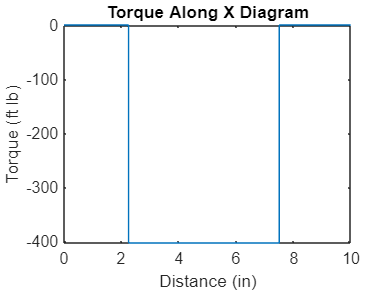

figure()
fplot(Tyz,[0 Lint])
title('Torque Along X Diagram')
xlabel('Distance (in)')
ylabel('Torque (ft lb)')

**Shaft Material Selection **

Select Trial Material: AISI 1020 CD Steel

**Shaft Design for Stress**

**Iteration 1:**

Critical points at gear 3 and 4 due to keyways. 

Gear 4 has maximum bending therefore stress calculations must be performed at it's location. 

Sut = 50 %kpsi 

Sut = 50

%Se'
Seprime = 0.5*Sut

Seprime = 25

a = 2

a = 2

b = -0.217

b = -0.2170

ka = a*Sut^b 

ka = 0.8558

kb = 0.879*1^-0.107

kb = 0.8790

%Pure Bending Assumed
kc = 1

kc = 1

%assume kd=1
ke = 0.753

ke = 0.7530

Se = Seprime*ka*kb*kc*ke

Se = 14.1605

%Chose Kf and Kfs to be 2 due to the fixation of the gear hub to the shaft
Kt = 2.14

Kt = 2.1400

q = 0.8 

q = 0.8000

Kts = 3

Kts = 3

qs = 0.84

qs = 0.8400

Kf = 1+q*(Kt+1)

Kf = 3.5120

Kfs = 1+q*(Kts+1)

Kfs = 4.2000

%A and B calc
Tm = T3

Tm = -403.5073

Ma = Mpeak

Ma = 3.9817e+03

A = abs(4*Kf*Ma)

A = 5.5936e+04

B = abs(3*Kfs*Tm)

B = 5.0842e+03

FOS = 1.2

FOS = 1.2000

D1 = ((8*FOS*A/(pi*Se*10^3)*(1+(1+ (2*B*Se*10^3/(A*Sut*10^3))^2 )^(1/2)))^(1/3))

D1 = 2.8908

Inital Diameter = 2.6625 in

A little large, choose stronger material

**Iteration 2, AISI 1035 CD:**

Sut = 186 %kpsi 

Sut = 186

%Se'
Seprime = 0.5*Sut

Seprime = 93

a = 2

a = 2

b = -0.217

b = -0.2170

ka = a*Sut^b 

ka = 0.6435

kb = 0.879*(D1)^-0.107

kb = 0.7846

%Pure Bending Assumed
kc = 1

kc = 1

%assume kd=1
ke = 0.753

ke = 0.7530

Se = Seprime*ka*kb*kc*ke

Se = 35.3577

%Chose Kf and Kfs to be 2 due to the fixation of the gear hub to the shaft
Kt = 2.14

Kt = 2.1400

q = 0.8 

q = 0.8000

kts = 3

kts = 3

qs = 0.84

qs = 0.8400

Kf = 1+q*(Kt+1)

Kf = 3.5120

Kfs = 1+q*(Kts+1)

Kfs = 4.2000

%A and B calc
Tm = T3

Tm = -403.5073

Ma = Mpeak

Ma = 3.9817e+03

A = abs(4*Kf*Ma)

A = 5.5936e+04

B = abs(3*Kfs*Tm)

B = 5.0842e+03

FOS = 1.2

FOS = 1.2000

D2 = ((8*FOS*A/(pi*Se*10^3)*(1+(1+ (2*B*Se*10^3/(A*Sut*10^3))^2 )^(1/2)))^(1/3))

D2 = 2.1306

**Bearing Specificaltion**

Rounding up diameter : 2.4 in

% Reaction forces (From part 7 18-1)
% B1z B2z B1y B2y

B1 = sqrt(B1z^2 + B1y^2)

B1 = 130.1223

B2 = sqrt(B2z^2 + B2y^2)

B2 = 1.8738e+03

BearingLife = 12000

BearingLife = 12000

LD = BearingLife * 60 * shaft_speed 

LD = 328000000


af = 1

af = 1

L10 = 10^6 %unknown

L10 = 1000000

xD = LD/L10

xD = 328

FD = B2 % for Bearing 2

FD = 1.8738e+03

x0 = 0.02 %assumed from textbook    

x0 = 0.0200

theta = 4.459

theta = 4.4590

rD = 0.995 % efficiency

rD = 0.9950

a = 3

a = 3

b = 1.483

b = 1.4830

FRB = af*FD*(xD/(x0 + (theta - x0)*((1-rD)^(1/b))))^(1/a)

FRB = 2.4617e+04


% Recalculate for roller bearings
% a = 10/3
a = 10/3 

a = 3.3333

FRB = af*FD*(xD/(x0 + (theta - x0)*((1-rD)^(1/b))))^(1/a)

FRB = 1.9028e+04

C = 33496.5

C = 3.3497e+04

ID = 1.57 %(40 mm)

ID = 1.5700

OD = 3.54 % 90 mm

OD = 3.5400

W = 1.3 % inches width

W = 1.3000

**Key Design**

% Factor of safety for the keys
key_FOS = 2

key_FOS = 2


% From Table 7-6 (pg 403) - assuming 58mm < shaft diameter <= 70mm 
% Choose square key:
t = 0.63/12 % 16mm x 16mm

t = 0.0525


d = 2.4/12 % use 2.4 in for now - shaft diameter at the position of the key/gears

d = 0.2000

F = abs(T4)/(d/2) % force on key at the surface of the shaft

F = 4.0351e+03


% Length of key limited by face width of gear
fw3/12

ans = 0.1667

fw4/12

ans = 0.2083


%yield strength for 1020 CD
Sy = 5.7e7 %psi

Sy = 57000000


% Prevent failure by crushing
l = 2*F*key_FOS/(t*Sy) % length of square key in feet

l = 0.0054